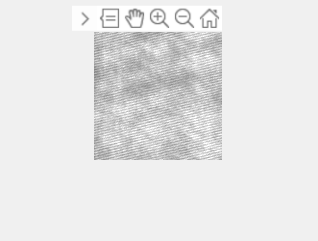

clear ;close all;clc;
imgPath = 'H:/SHUJU/denoising/data/1/cut_picture/10.bmp';         % 图像库路径
%imgsavePath = 'H:\SHUJU\denoising\ceshi\jieguo\';%图像保存路径
    

%第一步，选择背景几乎不变的图像区域求得噪声分布图
img=imread(imgPath);

[B,c,r]=roipoly(img);

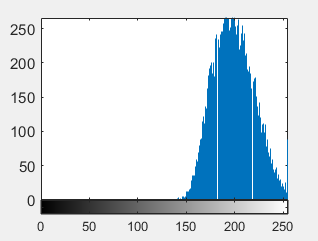

% g=[14 10 81 68];  %设置区域像素
% f=[157 235 197 118];
%B = roipoly(img,g,r);
[ counts , a ]=imhist(img(B));
beijing=sum(counts.*a)/sum(counts);
imhist(img(B))

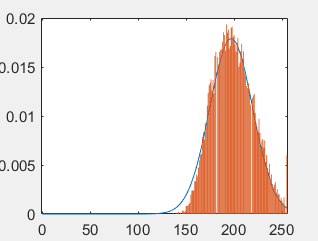

%第二步，求噪声分布数值所在区域的上下限
for i=1:length(counts)
    if (counts(i)>0) && (counts(i+1)>0)
        %upper_limlt表示最开始分布的数值
        upper_limlt = i;
        break
    end
end

for i2=upper_limlt:length(counts)-2
    if (counts(i2)==0) && (counts(i2+1)==0) && (counts(i2+2)==0)
        %under_limlt表示分布结束的数值
        under_limlt = i2;
        break
    else
        under_limlt = 255;
    end
end

%第三步，分析目标区域，得到预选的高斯分布均值
mean_value = (under_limlt+upper_limlt)/2;
fanwei = (under_limlt-upper_limlt)/10;
%第五步，将噪声直方图纵坐标转化为概率权重
area = sum(counts);
counts2 = counts/area;
%第六步，求出拟合程度最高的曲线
x=0:1:255;
zhan = 0;
sigma2=0;
mean2=0;
for mean=floor(mean_value-fanwei):1:round(mean_value+fanwei)
    for sigma = 1:0.1:100
        I = (1/(sigma*sqrt(2*pi))).*exp(-(x-mean).^2/(2*(sigma^2)));
        I = reshape(I,256,1);
        pearson = corr(I,counts2);
        if pearson>zhan
            zhan=pearson;
            sigma2 = sigma;
            mean2 = mean;
        end
    end
end
figure(1);
I = (1/(sigma2*sqrt(2*pi))).*exp(-(x-mean2).^2/(2*(sigma2^2)));
plot(x,I)
hold on
bar(a,counts2)

data = [mean2-beijing,sigma2];
imgsavePath = 'H:/SHUJU/denoising/data/1/cut_picture/';
save_path = [imgsavePath,'0.mat'];
save(save_path,'data');
clf


%第六步，求背景均值

% clear ;close all;clc;
% sigma=1;
% sigma2=2;
% mean=100;
% mean2=80;
% x=70:0.1:110
% I = (1/(sigma*sqrt(2*pi))).*exp(-(x-mean2).^2/(2*(sigma^2)));
% I2 = (1/(sigma2*sqrt(2*pi))).*exp(-(x-mean).^2/(2*(sigma2^2)));
% I3 = (1/(sigma*sqrt(2*pi))).*exp(-(x-mean).^2/(2*(sigma^2)));
% plot(x,I)
% hold on
% plot(x,I2)
% hold on
% plot(x,I3)
